load('Blanking Data.mat')

[~,~,~, rho] = atmosisa(0)

rho = 1.2250

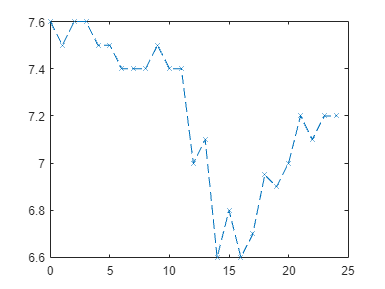


% free stream conditions
V_fs = 9; % freee Stream Velocity (m/s)
q_bar_fs = 1/2 * rho * V_fs^2;

% flow conditioins measured at the horizontal tail
alphas = BlankingData(1,:)'; % AoA (degrees)
Vs = BlankingData(3,:)'; % V (m/s)

plot(alphas, Vs, "--x")

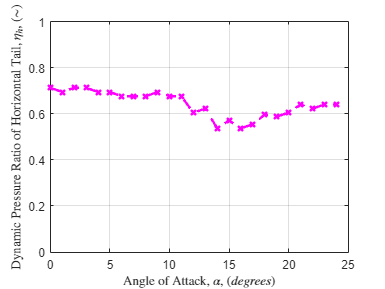


q_bar = 1/2 * rho * Vs.^2;

% compute horizontal tail planform effectiveness
eta_h = q_bar ./ q_bar_fs;

% save horizontal tail effectivness
save("Archytas_horizontal_Tail_Effectiveness" , "eta_h","alphas")

% plot eta_h
plot(alphas, eta_h, "m--x", "LineWidth", 2)
ylabel("Dynamic Pressure Ratio of Horizontal Tail, $\eta_h$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");
grid on
ylim([0,1])

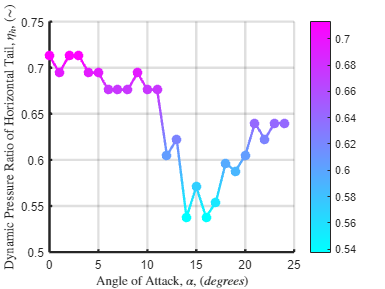


% try agian this time with colour gradient
figure
patch(alphas, eta_h, eta_h,'EdgeColor','interp','Marker','o','MarkerFaceColor','flat', "LineWidth", 2); colormap cool
colorbar;
ylabel("Dynamic Pressure Ratio of Horizontal Tail, $\eta_h$, $(\sim)$","Interpreter","latex");
xlabel("Angle of Attack, $\alpha$, $(degrees)$","Interpreter","latex");
grid on
set(gca,"LineWidth", 2)